# Process Quantitative EPMA Maps

## Import Data

 

clear all; close all; 

load batlowK.mat
FL     = {'FontSize',16};
FS     = {'FontSize',12};
Fs     = {'FontSize',10};
TX     = {'Interpreter','Latex'};
TL     = {'TicklabelInterpreter','Latex'};
LW     = {'LineWidth',2};
MS     = {'MarkerSize',10};
UN     = {'Units','inches'};

addpath ./data
filename = "VIC09A_B2-2_Oxide_Image_Classify.DAT";

opts = delimitedTextImportOptions("NumVariables", 18);

% Specify range and delimiter
opts.DataLines = [3, Inf];
opts.Delimiter = "\t";

% Specify column names and types
opts.VariableNames = ["Var1", "X", "Y", "NX", "NY", "NXY", "SiWT", "AlWT", "CaWT", "TiWT", "KWT", "PWT", "FeWT", "MnWT", "NaWT", "MgWT","OWT", "Total", "VarName18"];
opts.SelectedVariableNames = ["X", "Y", "NX", "NY", "NXY", "SiWT", "AlWT", "CaWT", "TiWT", "KWT", "PWT", "FeWT", "MnWT", "NaWT", "MgWT","OWT", "Total"];
opts.VariableTypes = ["string", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "Var1", "WhitespaceRule", "preserve");
opts = setvaropts(opts, "Var1", "EmptyFieldRule", "auto");
opts = setvaropts(opts, "VarName18", "TrimNonNumeric", true);
opts = setvaropts(opts, "VarName18", "ThousandsSeparator", ",");

% Import the data
DATtab = readtable(filename, opts);

disp('Data loaded successfully')

Data loaded successfully


## Convert data

 

% convert table to array
DATvec = table2array(DATtab);

% extract map dimensions
nx = max(DATvec(:,3));
nz = max(DATvec(:,4));
DATmap = reshape(DATvec,nx,nz,[]);
DATmap = permute(DATmap,[2,1,3]);

X  = DATmap(1,:,1).';
Z  = DATmap(:,1,2);

% sort oxides into standard sequence
%           Si Ti Al Fe Mg Ca  Na K  P  Mn O  Total
OxdInd   = [1, 4, 2, 7, 10, 3, 9, 5, 6, 8, 11, 12];
OxdNames = {'SiO2';'TiO2';'Al2O3';'FeO';'MgO';'CaO';'Na2O';'K2O'; 'P2O5'; 'MnO';'O';'Total'};
nc       = length(OxdInd);
Si = 1; Ti = 2; Al = 3; Fe = 4; Mg = 5; Ca = 6; Na = 7; K = 8; P = 9; Mn = 10; O = 11; Total = 12;
OxdVec = DATvec(:,5+OxdInd); OxdVec0 = OxdVec;
OxdMap = fliplr(DATmap(:,:,5+OxdInd));
OxdLim = {[0 90];[0 5];[0 30];[0 30];[0 30];[0 20];[0 10];[0 5];[0 5];[0 5]}; 

disp('Data converted successfully')

Data converted successfully


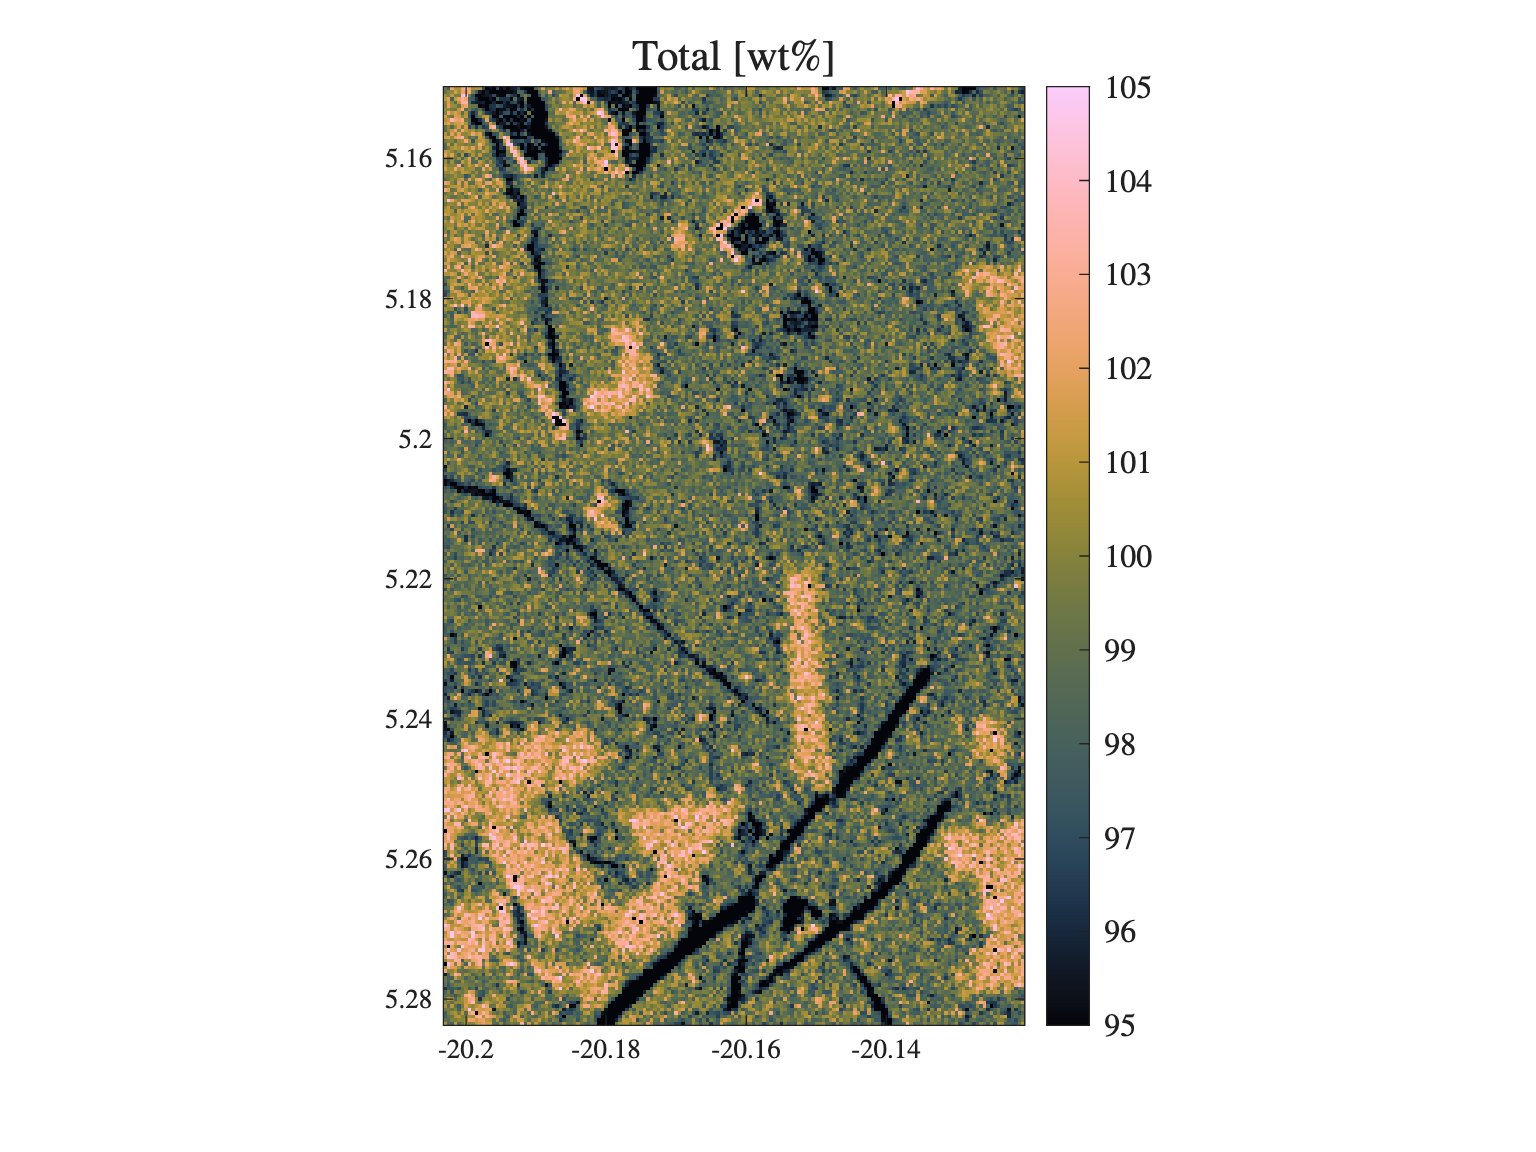

 

% extract valid totals
mintot =95;
maxtot =105;

valmap = OxdMap(:,:,Total)>mintot & OxdMap(:,:,Total)<maxtot;
valvec = OxdVec(:,Total)>mintot & OxdVec(:,Total)<maxtot;

fh1 = figure(1); clf;
set(fh1,UN{:},'Position',[1 1 8 6]);
imagesc(X,Z,OxdMap(:,:,Total).*valmap); axis equal tight; colormap(batlowK); colorbar(TL{:},FS{:}); 
clim([mintot,maxtot]);
set(gca,TL{:},Fs{:})
title('Total [wt\%]',TX{:},FL{:})

**Fig. 1:** Analytical totals of major oxide measurments of valid points between set min/max tolerance levels.

## Plot major element oxide maps

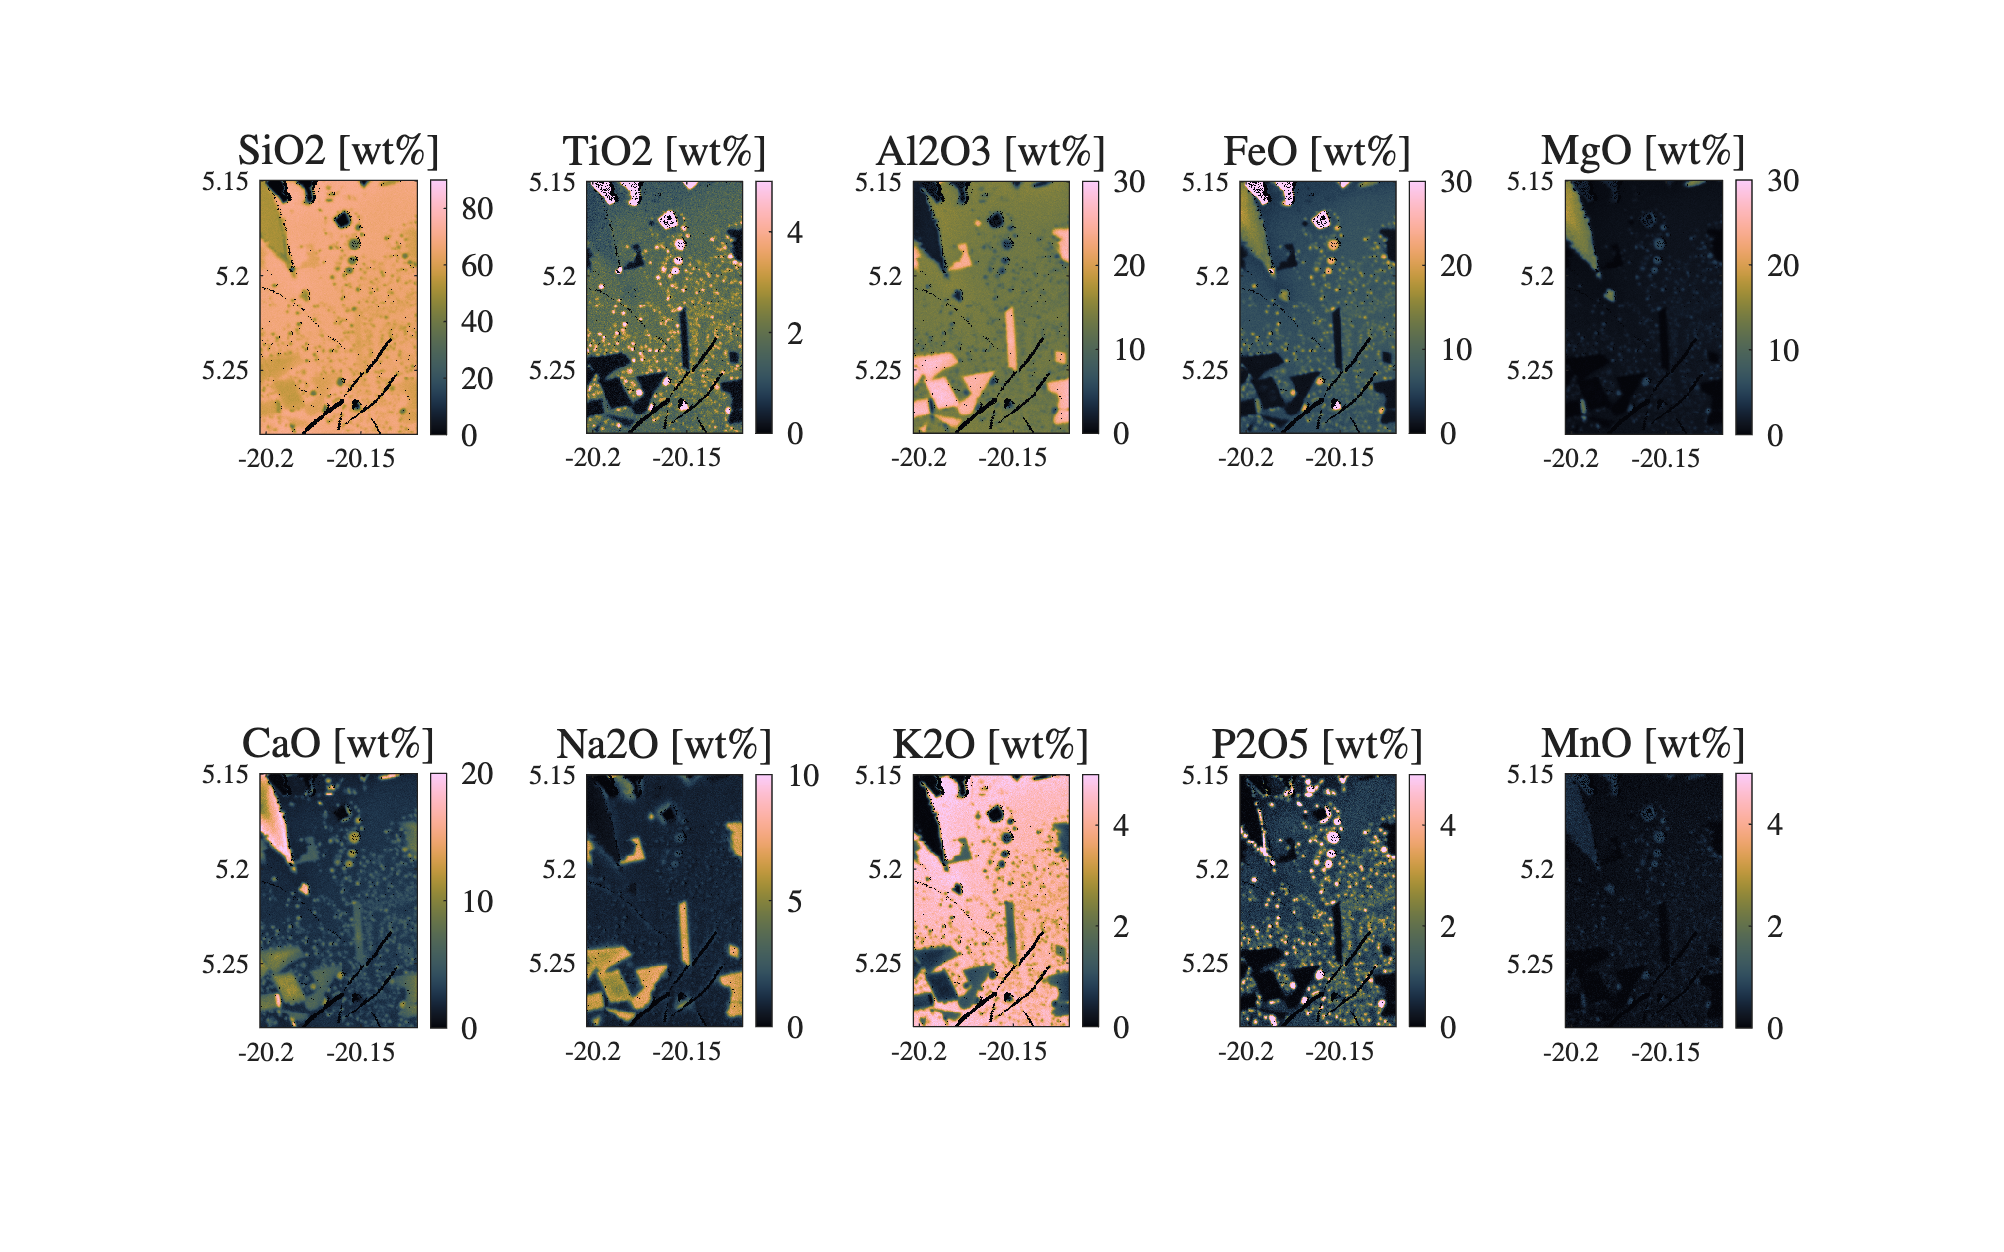

% plot oxide compositions

 

fh2 = figure(2); clf;
set(fh2,UN{:},'Position',[1 1 24 15]);
k  = nc-2;
if     k<=4;  kk = 2; kkk = 2; 
elseif k<=6;  kk = 2; kkk = 3;
elseif k<=8;  kk = 2; kkk = 4;
elseif k<=9;  kk = 3; kkk = 3;
elseif k<=10; kk = 2; kkk = 5;
end

ik = 1;
for ikk=1:kk
    for ikkk = 1:kkk
        subplot(kk,kkk,ik);
        imagesc(X,Z,OxdMap(:,:,ik).*valmap); axis equal tight; 
        colormap(batlowK); colorbar(TL{:},FS{:});
        clim(OxdLim{ik});
        set(gca,TL{:},Fs{:})
        title([OxdNames{ik},' [wt\%]'],TX{:},FL{:})
        ik = ik+1;
    end
end

**Fig. 2:** Major oxide concentrations; colorbar range cropped to improve readability.

## Plot Correlation Matrix

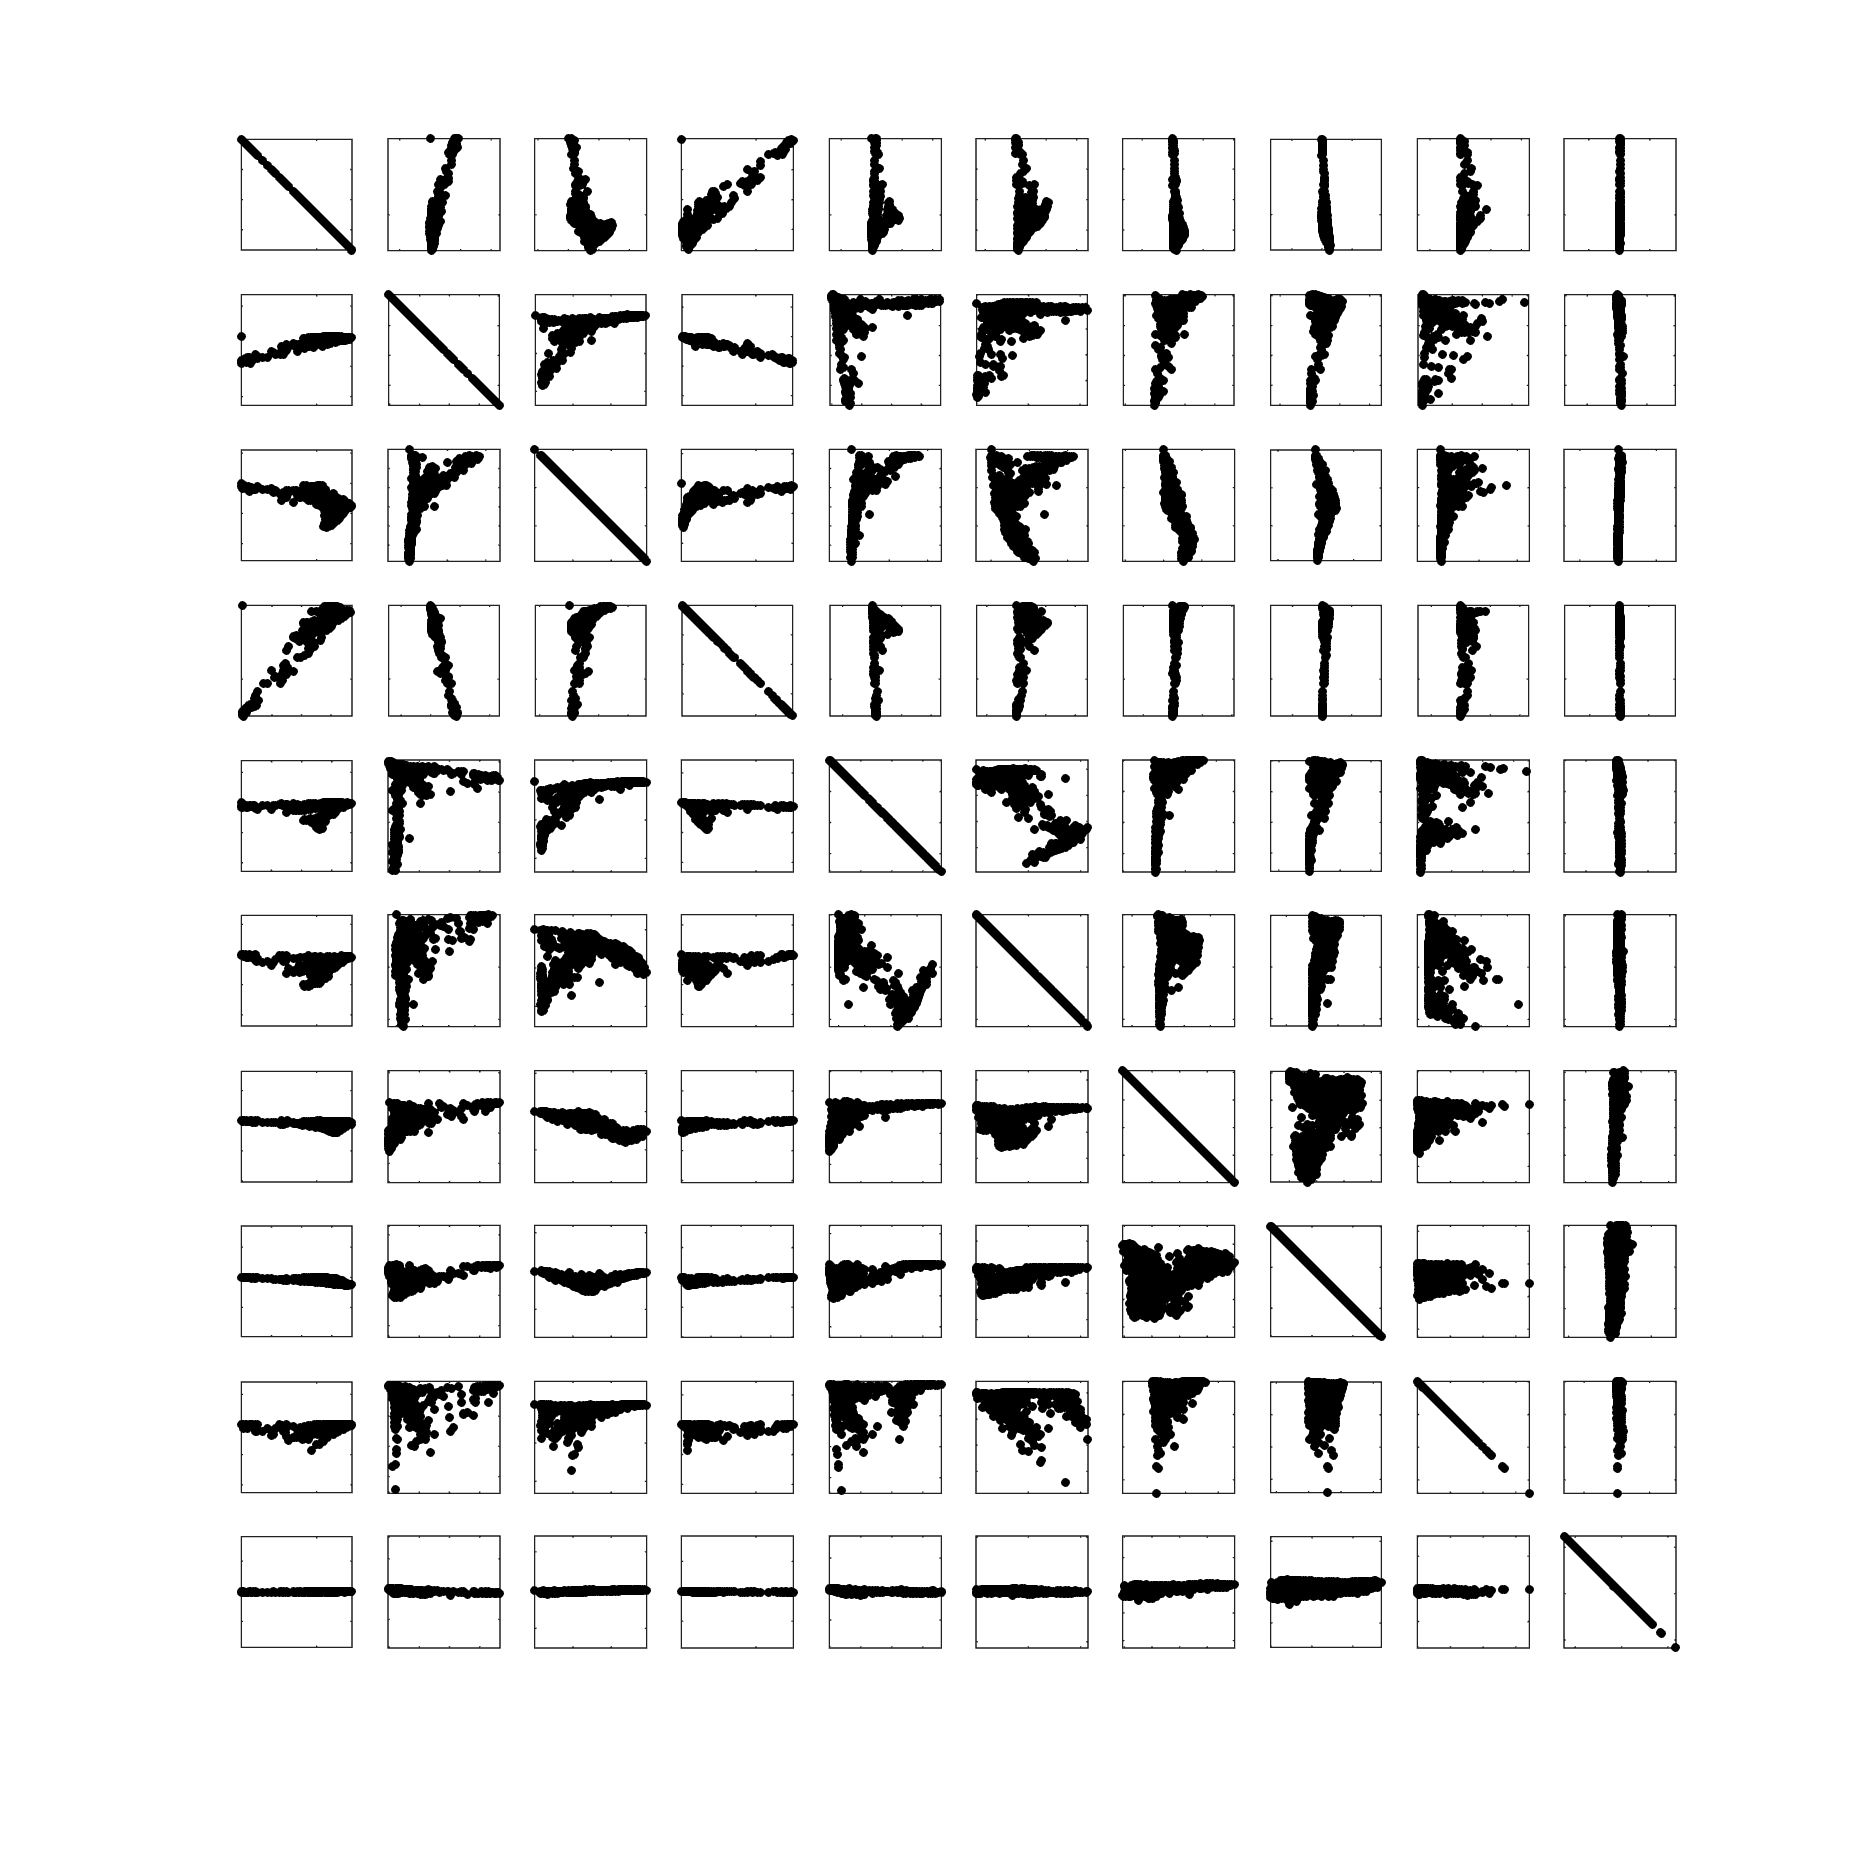

 

fh3 = figure(3); clf;
set(fh3,UN{:},'Position',[1 1 20 20]);
k  = nc-2;
ik = 1;
for kk=1:k
    for kkk = 1:k
        subplot(k,k,ik);
        plot(OxdVec(1:10:end,kkk).*valvec(1:10:end),OxdVec(1:10:end,kk).*valvec(1:10:end),'k.',MS{:}); axis ij equal;
        set(gca,'XTickLabels',[],'YTickLabels',[]);
        ik = ik+1;
    end
end

**Fig. 3:** Correlation between major oxide concentrations.

## Plot False Colour Images

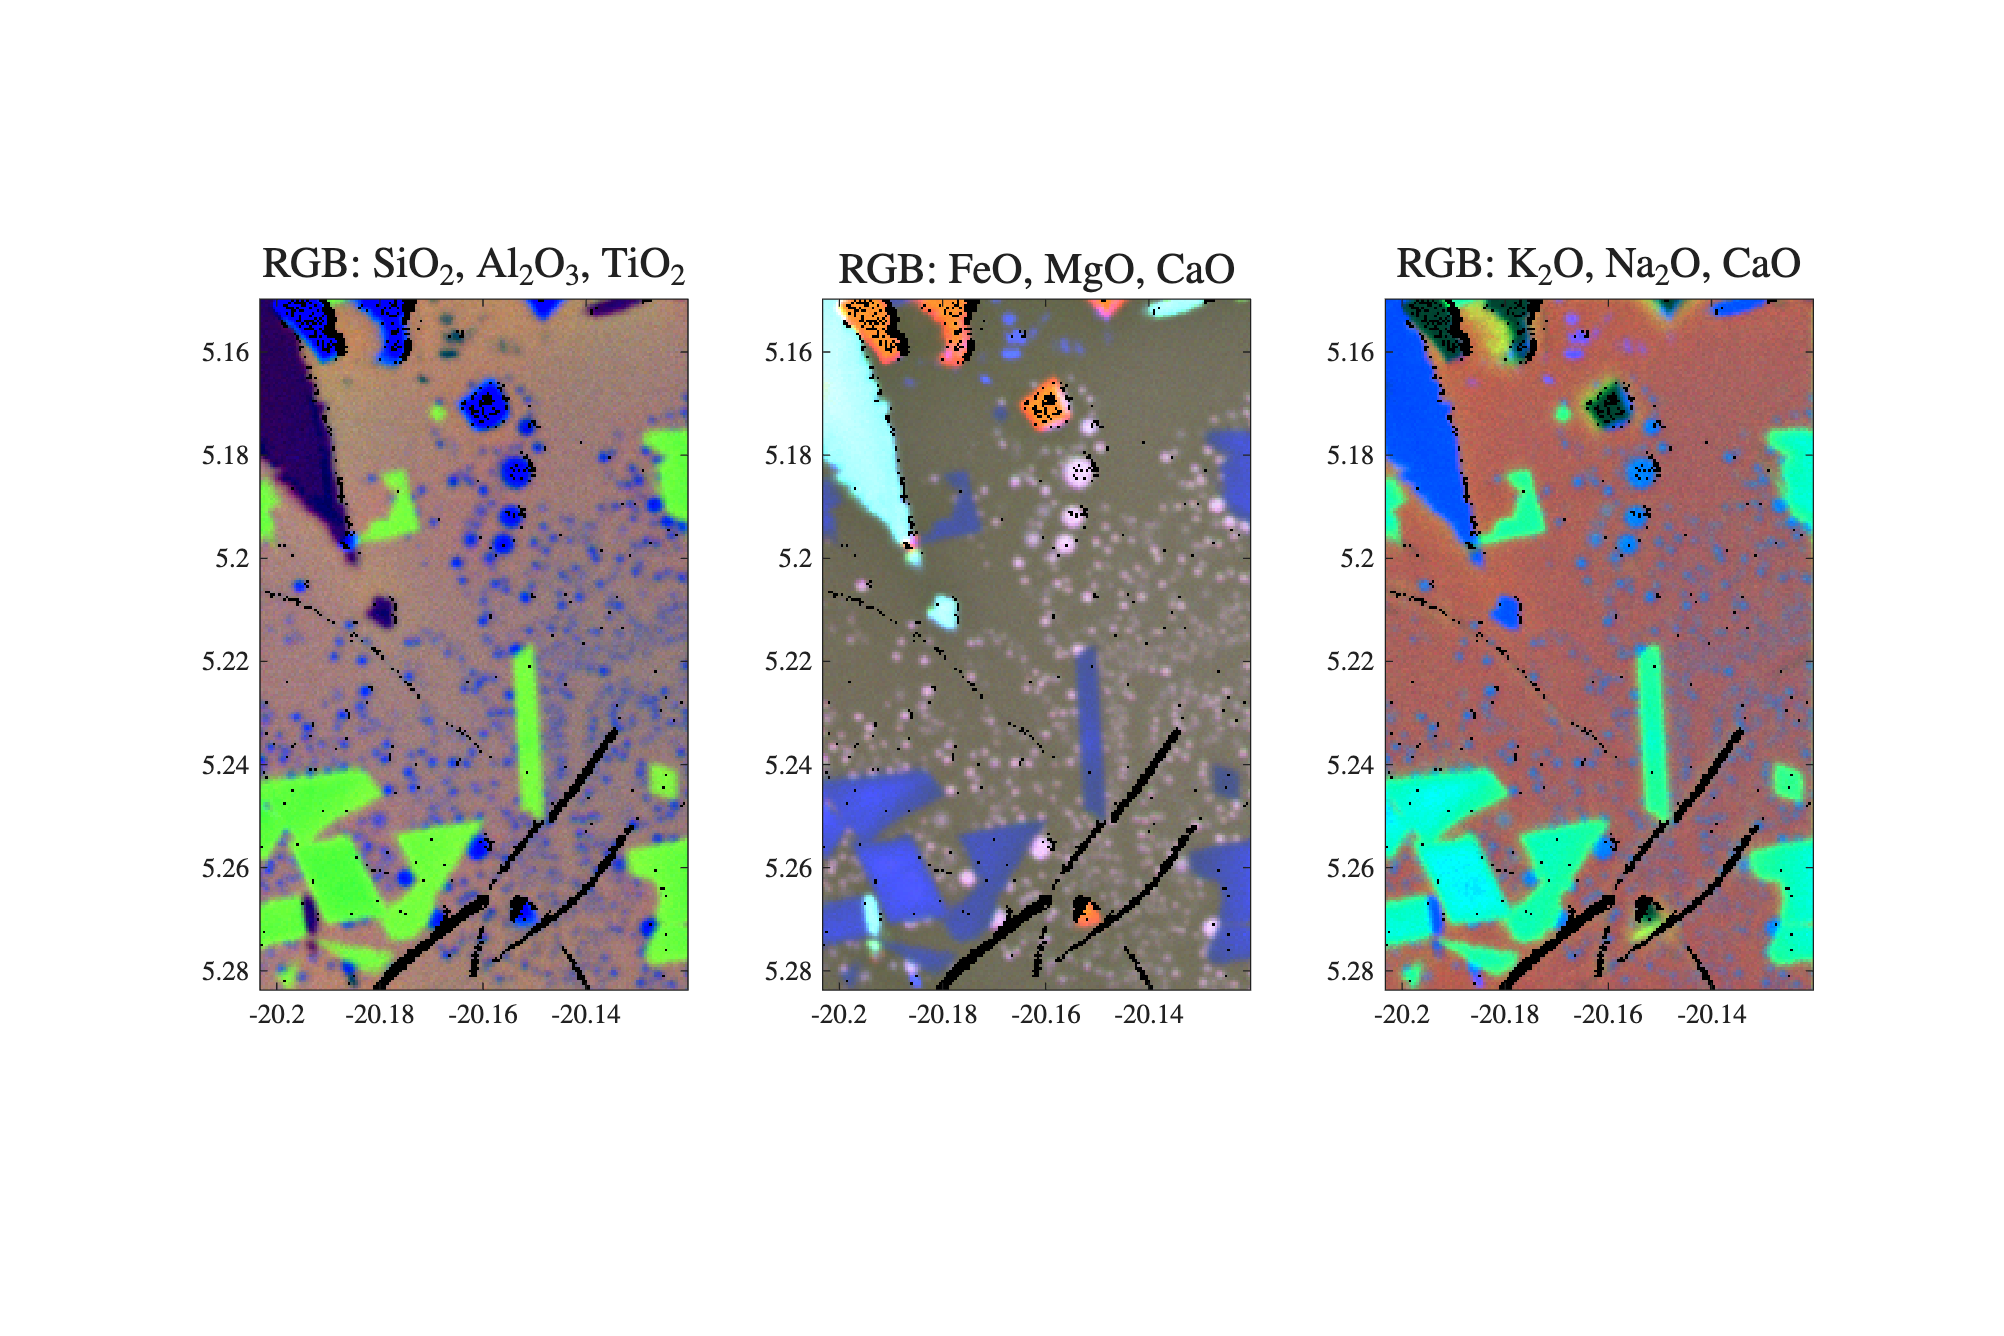

 

sat = 2;

fh4 = figure(4); clf;
set(fh4,UN{:},'Position',[1 1 12 8]);

subplot(1,3,1)
RGB = OxdVec(:,[Si,Al,Ti]);
RGB = valvec.*(RGB - (mean(RGB(valvec,:))-sat*std(RGB(valvec,:)))) ./ ((mean(RGB(valvec,:))+sat*std(RGB(valvec,:))) - (mean(RGB(valvec,:))-sat*std(RGB(valvec,:))));
imagesc(X,Z,fliplr(permute(reshape(RGB,nx,nz,[]),[2,1,3]))); axis equal tight;
set(gca,TL{:},Fs{:})
title('RGB: SiO$_2$, Al$_2$O$_3$, TiO$_2$',TX{:},FL{:})

subplot(1,3,2)
RGB = OxdVec(:,[Fe,Mg,Ca]);
RGB = valvec.*(RGB - (mean(RGB(valvec,:))-sat*std(RGB(valvec,:)))) ./ ((mean(RGB(valvec,:))+sat*std(RGB(valvec,:))) - (mean(RGB(valvec,:))-sat*std(RGB(valvec,:))));
imagesc(X,Z,fliplr(permute(reshape(RGB,nx,nz,[]),[2,1,3]))); axis equal tight;
set(gca,TL{:},Fs{:})
title('RGB: FeO, MgO, CaO',TX{:},FL{:})

subplot(1,3,3)
RGB = OxdVec(:,[K,Na,Ca]);
RGB = valvec.*(RGB - (mean(RGB(valvec,:))-sat*std(RGB(valvec,:)))) ./ ((mean(RGB(valvec,:))+sat*std(RGB(valvec,:))) - (mean(RGB(valvec,:))-sat*std(RGB(valvec,:))));
imagesc(X,Z,fliplr(permute(reshape(RGB,nx,nz,[]),[2,1,3]))); axis equal tight;
set(gca,TL{:},Fs{:})
title('RGB: K$_2$O, Na$_2$O, CaO',TX{:},FL{:})

**Fig. 4:** False-colour images of raw oxide data showing images of (left to right) RGB = [TiO2, SiO2, Al2O3]; [FeO, MgO, CaO]; [K2O, Na2O, CaO].

## Filter and Scale Data

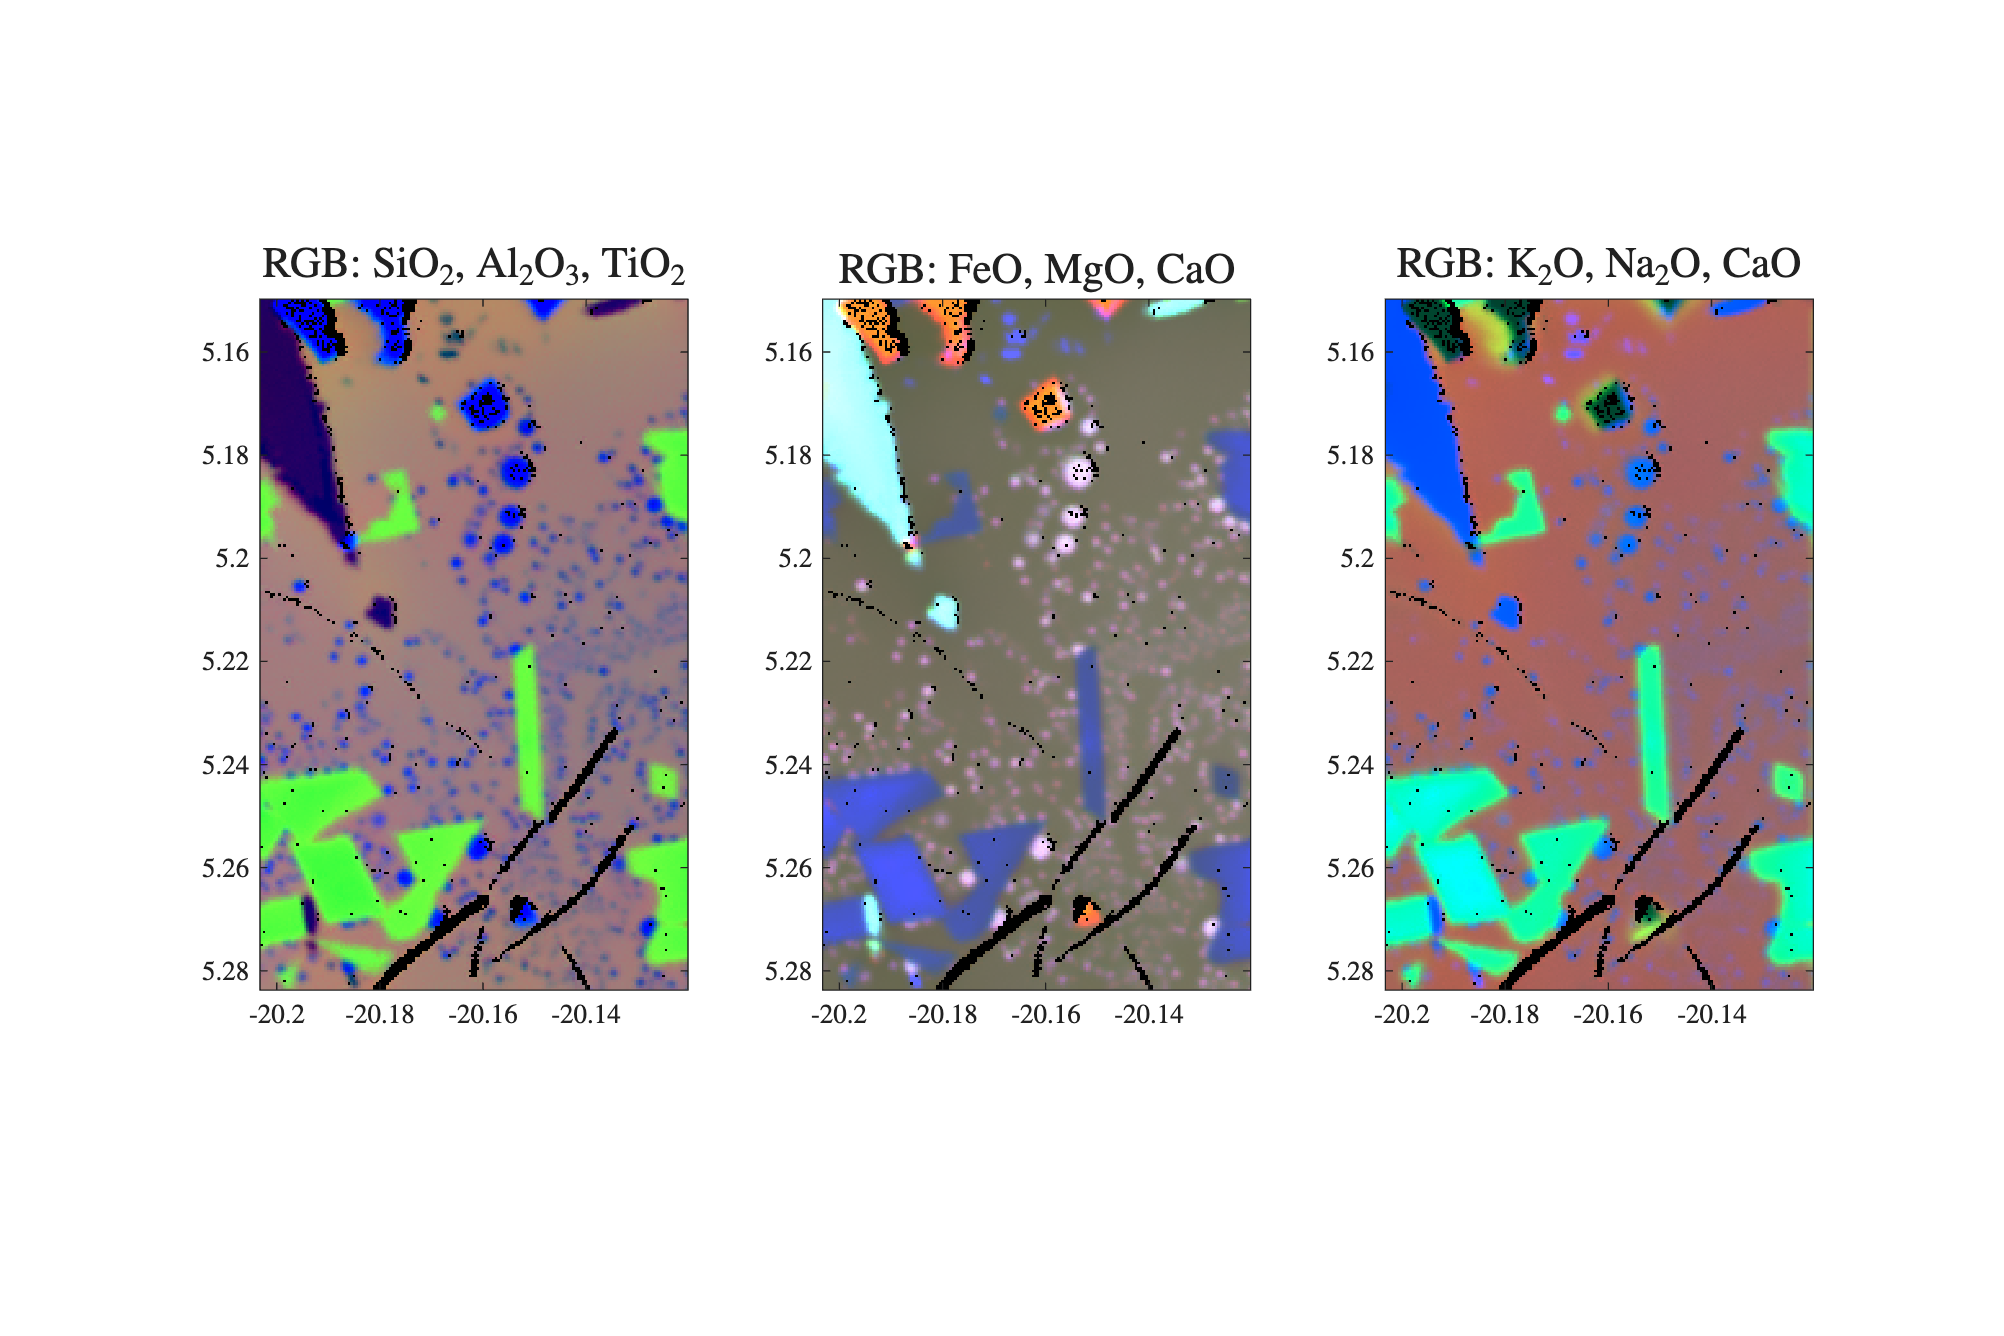

 

smth = 0.4;

for i = 1:k
    MAP = reshape(OxdVec0(:,i).*valvec,nx,nz);
    MAP = imnlmfilt(MAP,'DegreeOfSmoothing',smth);
    OxdVec(:,i) = MAP(:);
end

% normalise data to unit sum for relative intensities
OxdVec(:,1:k)  =  OxdVec(:,1:k)./(sum(OxdVec(:,1:k),2)+1e-32);

% plot filtered and rescaled results
fh5 = figure(5); clf;
set(fh5,UN{:},'Position',[1 1 12 8]);

subplot(1,3,1)
RGB = OxdVec(:,[Si,Al,Ti]);
RGB = valvec.*(RGB - (mean(RGB(valvec,:))-sat*std(RGB(valvec,:)))) ./ ((mean(RGB(valvec,:))+sat*std(RGB(valvec,:))) - (mean(RGB(valvec,:))-sat*std(RGB(valvec,:))));
imagesc(X,Z,fliplr(permute(reshape(RGB,nx,nz,[]),[2,1,3]))); axis equal tight;
set(gca,TL{:},Fs{:})
title('RGB: SiO$_2$, Al$_2$O$_3$, TiO$_2$',TX{:},FL{:})

subplot(1,3,2)
RGB = OxdVec(:,[Fe,Mg,Ca]);
RGB = valvec.*(RGB - (mean(RGB(valvec,:))-sat*std(RGB(valvec,:)))) ./ ((mean(RGB(valvec,:))+sat*std(RGB(valvec,:))) - (mean(RGB(valvec,:))-sat*std(RGB(valvec,:))));
imagesc(X,Z,fliplr(permute(reshape(RGB,nx,nz,[]),[2,1,3]))); axis equal tight;
set(gca,TL{:},Fs{:})
title('RGB: FeO, MgO, CaO',TX{:},FL{:})

subplot(1,3,3)
RGB = OxdVec(:,[K,Na,Ca]);
RGB = valvec.*(RGB - (mean(RGB(valvec,:))-sat*std(RGB(valvec,:)))) ./ ((mean(RGB(valvec,:))+sat*std(RGB(valvec,:))) - (mean(RGB(valvec,:))-sat*std(RGB(valvec,:))));
imagesc(X,Z,fliplr(permute(reshape(RGB,nx,nz,[]),[2,1,3]))); axis equal tight;
set(gca,TL{:},Fs{:})
title('RGB: K$_2$O, Na$_2$O, CaO',TX{:},FL{:})

**Fig. 5:** False-colour images of filtered and rescaled oxide data showing images of (left to right) RGB = [TiO2, SiO2, Al2O3]; [FeO, MgO, CaO]; [K2O, Na2O, CaO].

## Perform Principal Component Analysis

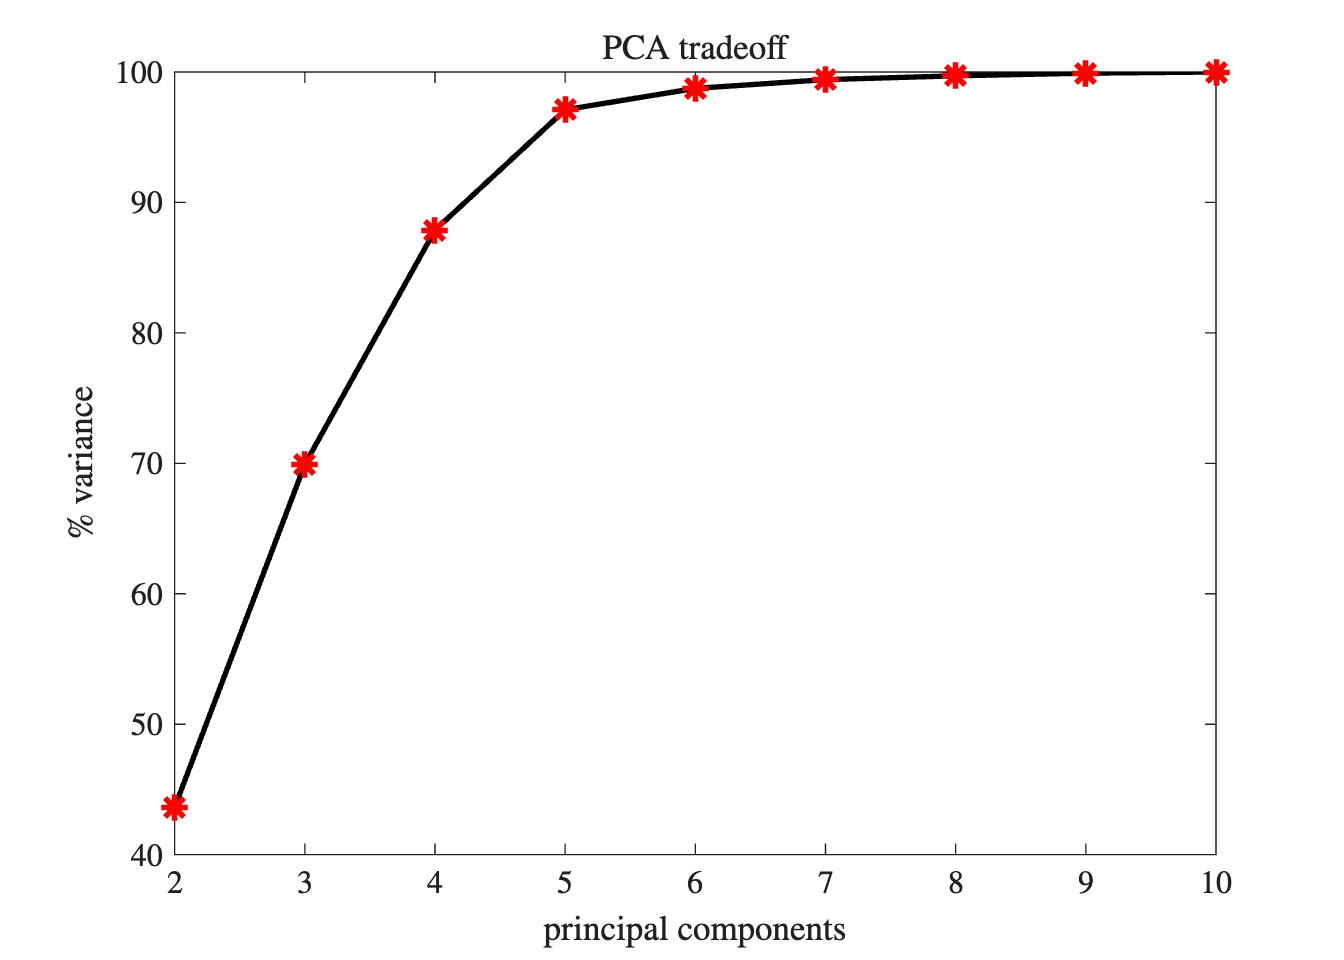

 

% perform principal component analysis
[PC, PA, PV] = pca(OxdVec(valvec,1:k),'Algorithm','svd','Centered','on','VariableWeights','variance');
PC = PC.';
CV = cumsum(PV(1:end-1)./sum(PV(1:end-1)));

% plot tradeoff curve
fh6 = figure(6); clf;
set(fh6,UN{:},'Position',[1 1 7 5]);

plot(2:k,CV*100,'k-',2:k,CV*100,'r*',LW{:},MS{:})
title('PCA tradeoff',TX{:},FL{:})
xlabel('principal components',TX{:},FL{:})
ylabel('\% variance',TX{:},FL{:})
set(gca,TL{:},FS{:},'Xtick',2:k)

**Fig. 6:** Principal component tradeoff curve showing cumulative percentage of variance versus number of principal components retained.

## Reduce Data Dimensions

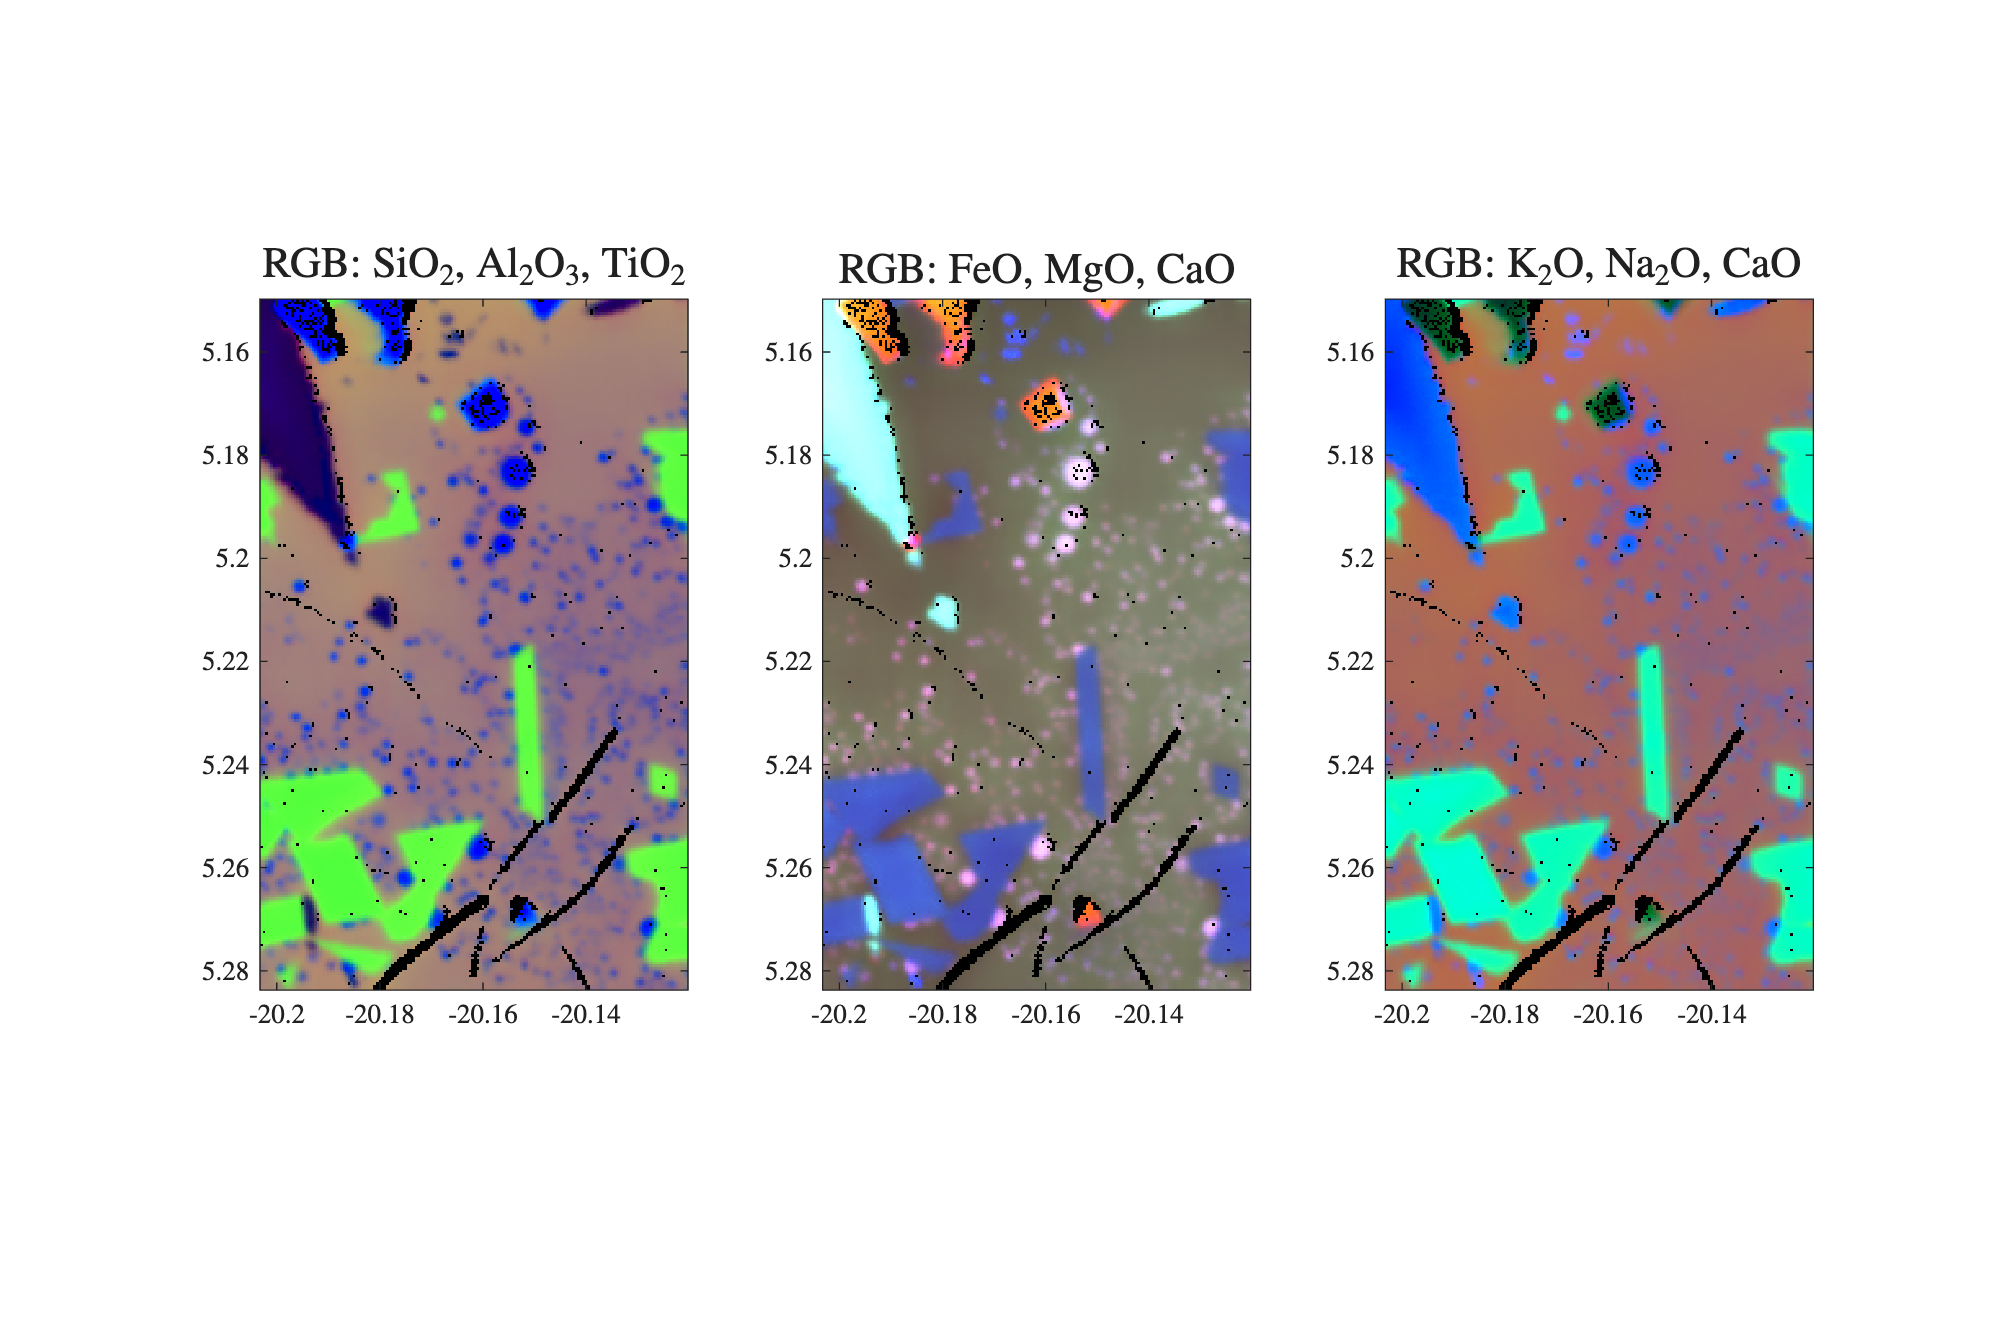

 

p =4;

% reduce data to p principal components
Fp = PC(1:p,:);
Ap = zeros(size(OxdVec,1),p);
Ap(valvec,:) = PA(:,1:p);
OxdPC = Ap*Fp + mean(OxdVec(:,1:k).*valvec);
Rp = sum((OxdPC-OxdVec(:,1:k).*valvec).^2,2)./sum((OxdVec(:,1:k).*valvec).^2,2);

fh7 = figure(7); clf;
set(fh7,UN{:},'Position',[1 1 12 8]);

subplot(1,3,1)
RGB = OxdPC(:,[Si,Al,Ti]);
RGB = valvec.*(RGB - (mean(RGB(valvec,:))-sat*std(RGB(valvec,:)))) ./ ((mean(RGB(valvec,:))+sat*std(RGB(valvec,:))) - (mean(RGB(valvec,:))-sat*std(RGB(valvec,:))));
imagesc(X,Z,fliplr(permute(reshape(RGB,nx,nz,[]),[2,1,3]))); axis equal tight;
set(gca,TL{:},Fs{:})
title('RGB: SiO$_2$, Al$_2$O$_3$, TiO$_2$',TX{:},FL{:})

subplot(1,3,2)
RGB = OxdPC(:,[Fe,Mg,Ca]);
RGB = valvec.*(RGB - (mean(RGB(valvec,:))-sat*std(RGB(valvec,:)))) ./ ((mean(RGB(valvec,:))+sat*std(RGB(valvec,:))) - (mean(RGB(valvec,:))-sat*std(RGB(valvec,:))));
imagesc(X,Z,fliplr(permute(reshape(RGB,nx,nz,[]),[2,1,3]))); axis equal tight;
set(gca,TL{:},Fs{:})
title('RGB: FeO, MgO, CaO',TX{:},FL{:})

subplot(1,3,3)
RGB = OxdPC(:,[K,Na,Ca]);
RGB = valvec.*(RGB - (mean(RGB(valvec,:))-sat*std(RGB(valvec,:)))) ./ ((mean(RGB(valvec,:))+sat*std(RGB(valvec,:))) - (mean(RGB(valvec,:))-sat*std(RGB(valvec,:))));
imagesc(X,Z,fliplr(permute(reshape(RGB,nx,nz,[]),[2,1,3]))); axis equal tight;
set(gca,TL{:},Fs{:})
title('RGB: K$_2$O, Na$_2$O, CaO',TX{:},FL{:})

**Fig. 7:** False-colour images of reduced data showing images of (left to right) RGB = [TiO2, SiO2, Al2O3]; [FeO, MgO, CaO]; [K2O, Na2O, CaO].

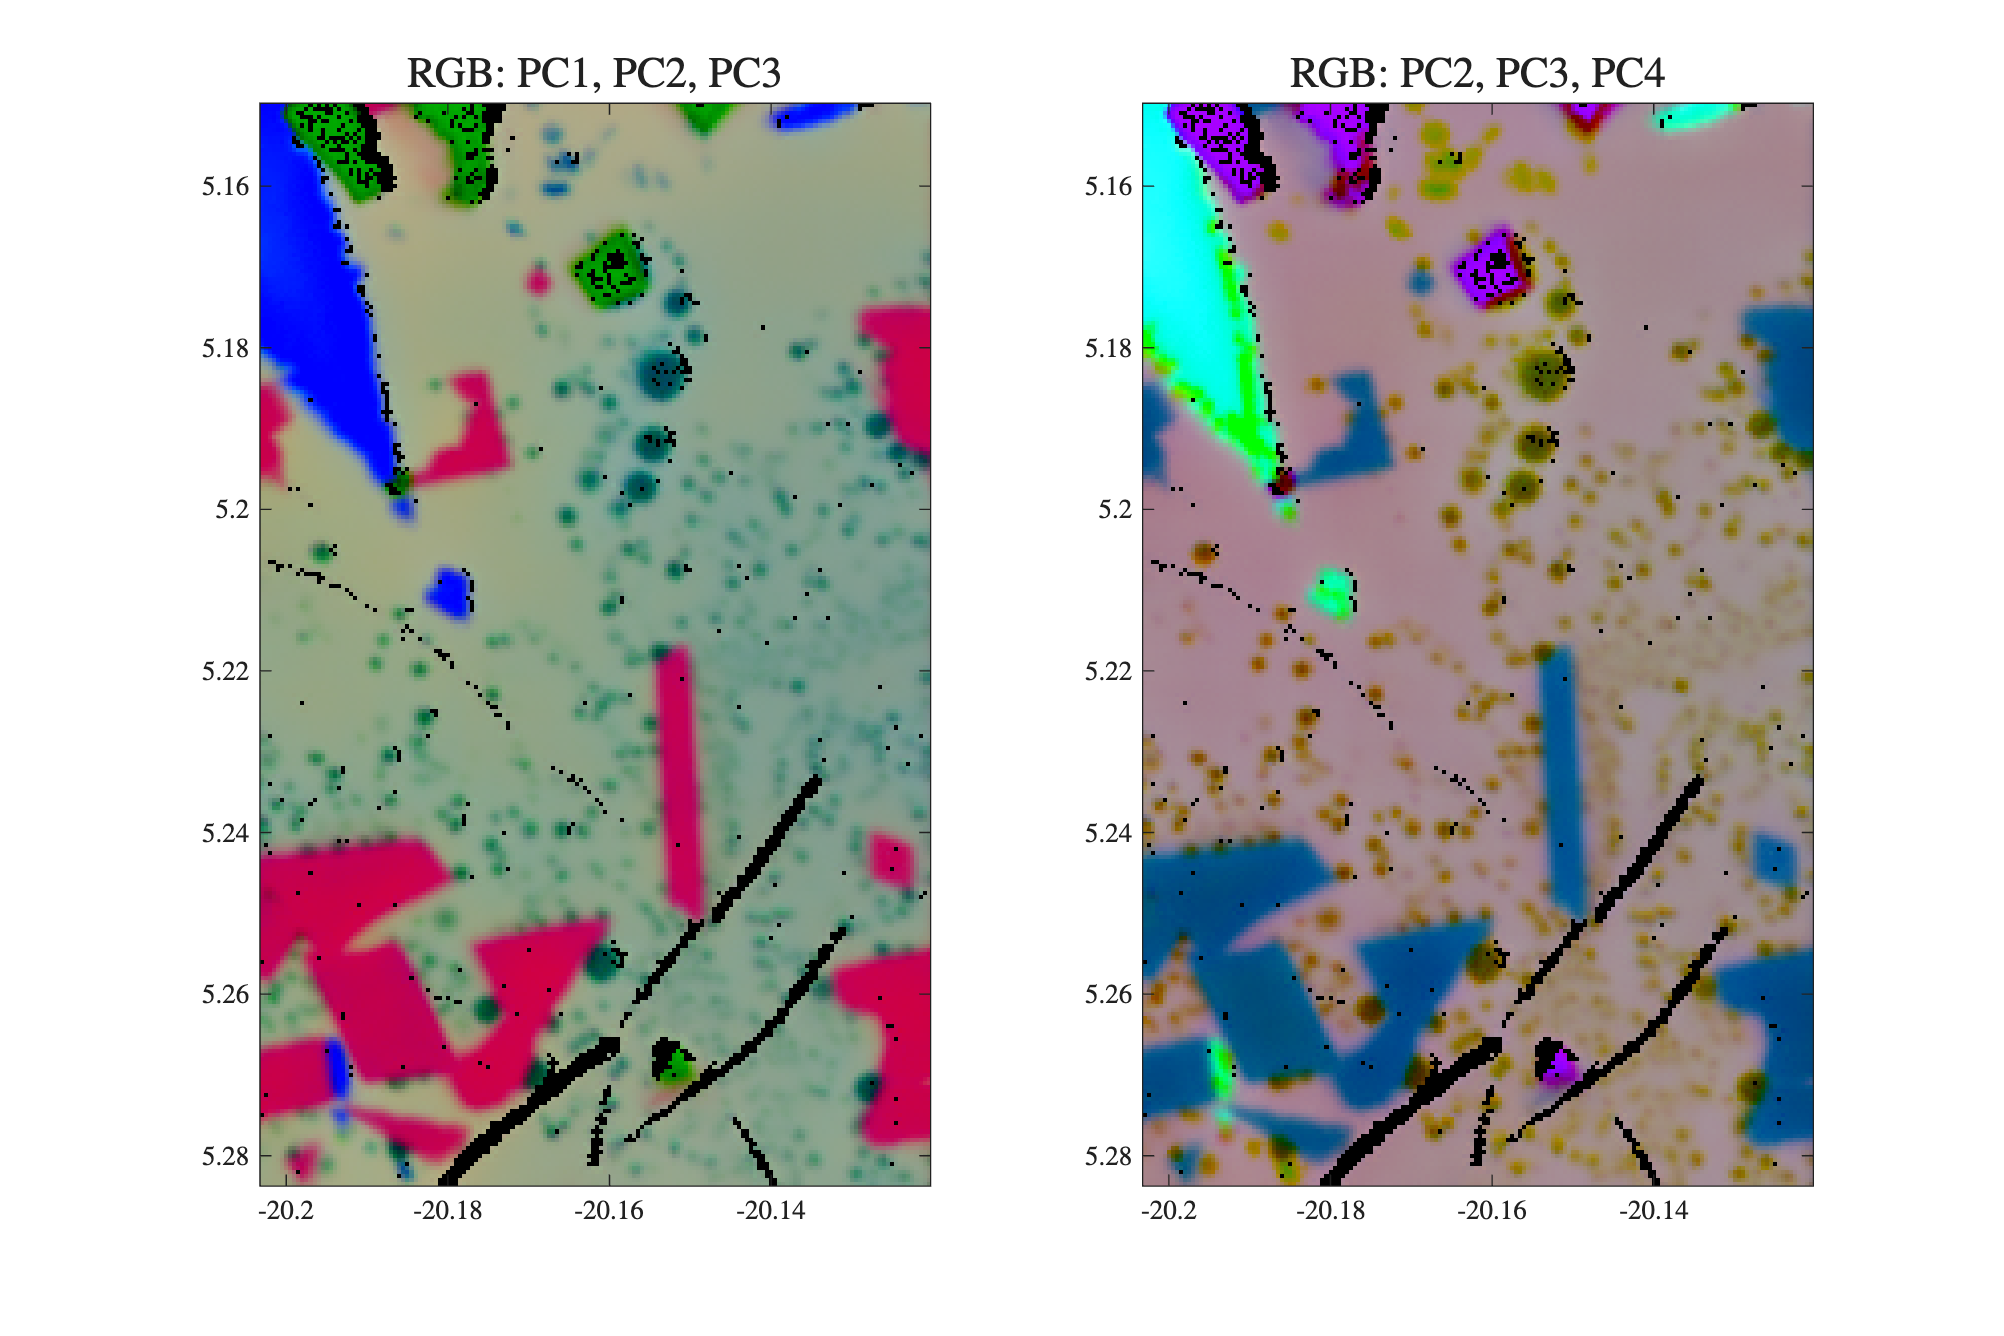

fh8 = figure(8); clf;
set(fh8,UN{:},'Position',[1 1 12 8]);

subplot(1,2,1)
ic = [1,2,min(3,p)];
RGB = Ap(:,ic);
RGB = valvec.*(RGB - (mean(RGB(valvec,:))-sat*std(RGB(valvec,:)))) ./ ((mean(RGB(valvec,:))+sat*std(RGB(valvec,:))) - (mean(RGB(valvec,:))-sat*std(RGB(valvec,:))));
imagesc(X,Z,fliplr(permute(reshape(RGB,nx,nz,[]),[2,1,3]))); axis equal tight;
set(gca,TL{:},Fs{:})
title(['RGB: PC',int2str(ic(1)),', PC',int2str(ic(2)),', PC',int2str(ic(3))],TX{:},FL{:})

subplot(1,2,2)
ic = [max(1,p-2),max(2,p-1),max(2,p)];
RGB = Ap(:,ic);
RGB = valvec.*(RGB - (mean(RGB(valvec,:))-sat*std(RGB(valvec,:)))) ./ ((mean(RGB(valvec,:))+sat*std(RGB(valvec,:))) - (mean(RGB(valvec,:))-sat*std(RGB(valvec,:))));
imagesc(X,Z,fliplr(permute(reshape(RGB,nx,nz,[]),[2,1,3]))); axis equal tight;
set(gca,TL{:},Fs{:})
title(['RGB: PC',int2str(ic(1)),', PC',int2str(ic(2)),', PC',int2str(ic(3))],TX{:},FL{:})

## Perform Clustering Analysis

 

c =6;

% perform fuzzy c-means clustering analysis
rng(15);

data = Ap(valvec,:);   % N x D
m    = 2.0;            % fuzziness exponent 
maxIter = 1e3;
minImpr = 1e-5;        % stop
display = 1;           

% options = [m maxIter minImpr display]
[Fc, U] = fcm(data, c, [m maxIter minImpr display]);  % Fc: c x D, U: c x N

Iteration count = 1, obj. fcn = 92594.6
Iteration count = 2, obj. fcn = 69631.7
Iteration count = 3, obj. fcn = 69627
Iteration count = 4, obj. fcn = 69601.5
Iteration count = 5, obj. fcn = 69461.9
Iteration count = 6, obj. fcn = 68764.4
Iteration count = 7, obj. fcn = 66465.3
Iteration count = 8, obj. fcn = 63500.9
Iteration count = 9, obj. fcn = 61027.9
Iteration count = 10, obj. fcn = 57240.5
Iteration count = 11, obj. fcn = 49147.1
Iteration count = 12, obj. fcn = 43211.1
Iteration count = 13, obj. fcn = 39787.5
Iteration count = 14, obj. fcn = 36706.7
Iteration count = 15, obj. fcn = 34750.8
Iteration count = 16, obj. fcn = 34293.1
Iteration count = 17, obj. fcn = 34099.2
Iteration count = 18, obj. fcn = 33683.9
Iteration count = 19, obj. fcn = 32521.2
Iteration count = 20, obj. fcn = 30007.1
Iteration count = 21, obj. fcn = 27418.5
Iteration count = 22, obj. fcn = 26425.9
Iteration count = 23, obj. fcn = 26229.8
Iteration count = 24, obj. fcn = 26187.7
Iteration count = 25, obj. 

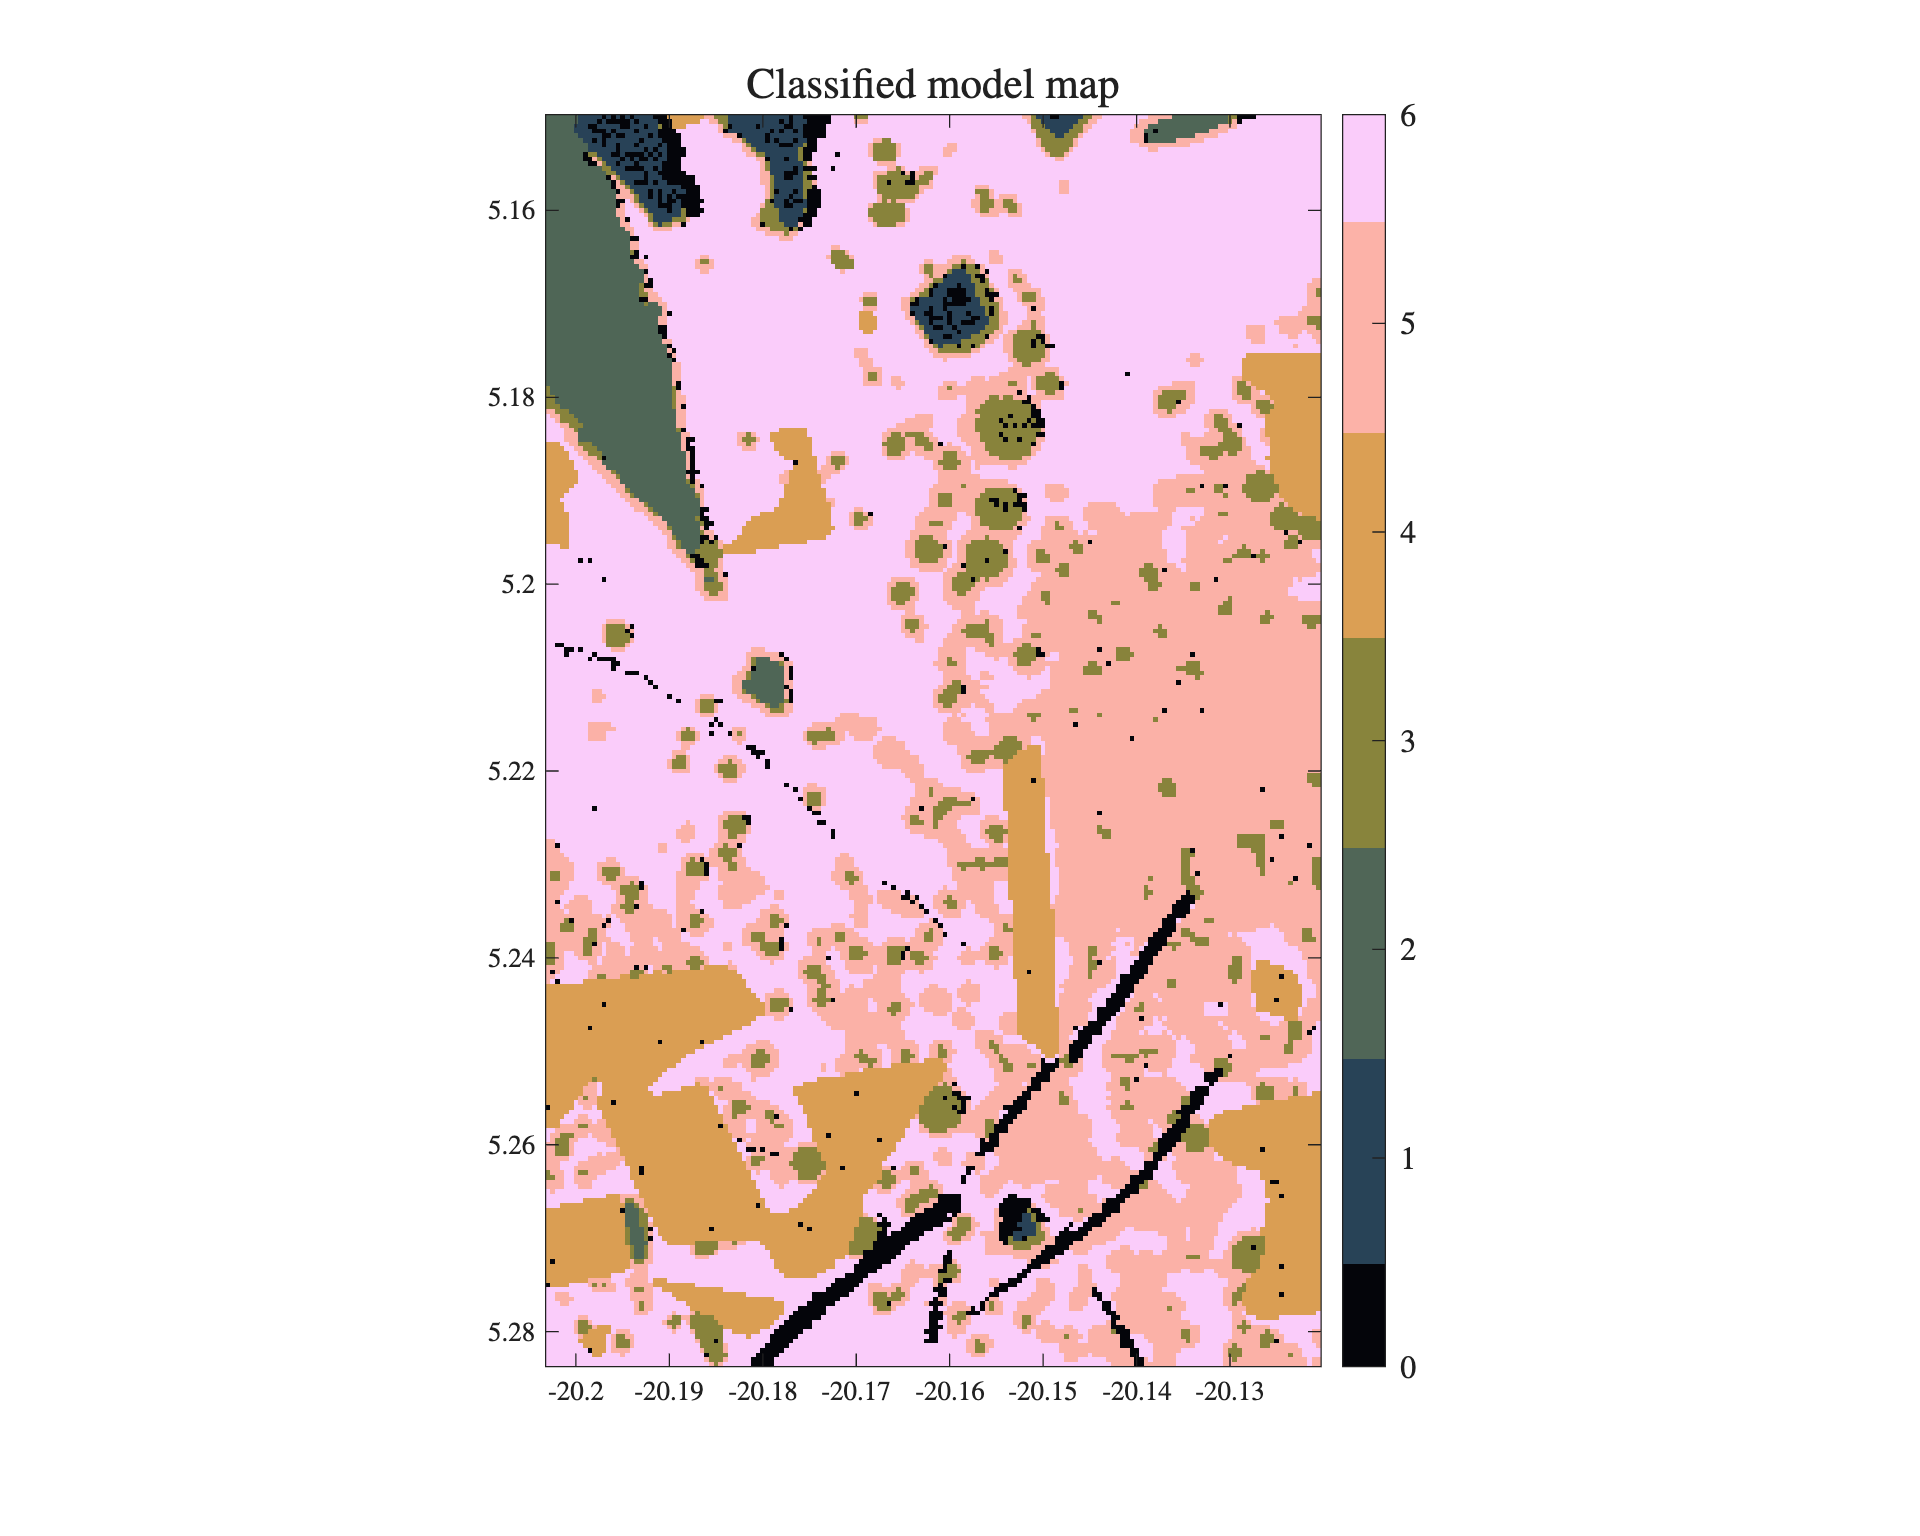


% convert fuzzy memberships to hard labels for plotting (Ic in 1..c)
[~, Ic] = max(U, [], 1);     % 1 x N

% full label vector (0 means unclassified/outside valvec, consistent with your plotting)
Icfull = zeros(size(valvec));
Icfull(valvec,1) = Ic(:);
% get cluster compositions in oxides
ClstOxdMean = zeros(c,k);
ClstOxdStd  = zeros(c,k);
for ic = 1:c
    w = (U(ic,:).^m).';   % N x 1 weights for cluster ic
   
    % weighted mean
    ClstOxdMean(ic,:) = sum(w .* (OxdVec(valvec,1:k)), 1) ./ sum(w);

    % weighted std (population-style, weighted)
    dif = (OxdVec(valvec,1:k)) - (sum(w .* (OxdVec(valvec,1:k)), 1) ./ sum(w));
    ClstOxdStd(ic,:) = sqrt( sum(w .* (dif.^2), 1) ./ sum(w) );
end

% sort clusters for ascending SiO2 content
[~,isort]   = sort(ClstOxdMean(:,1),'ascend');
ClstOxdMean = ClstOxdMean(isort,:);
ClstOxdStd  = ClstOxdStd (isort,:);
Icfull_sort = zeros(size(valvec));
for ic = 1:c
    Icfull_sort(Icfull==isort(ic)) = ic;
end
Icfull = Icfull_sort;

% plot trained model map
ColorClass = batlowK(max(1,min(256,1+round((1:256)/(256/c))*round(256/c))),:);

fh9 = figure(9); clf;
set(fh9,'Units','inches','Position',[1 1 10 8]);

imagesc(X,Z,fliplr(reshape(Icfull,nx,nz).')); colormap(ColorClass); colorbar(TL{:},FS{:}); axis equal tight;
title('Classified model map',FL{:},TX{:})
set(gca,TL{:})

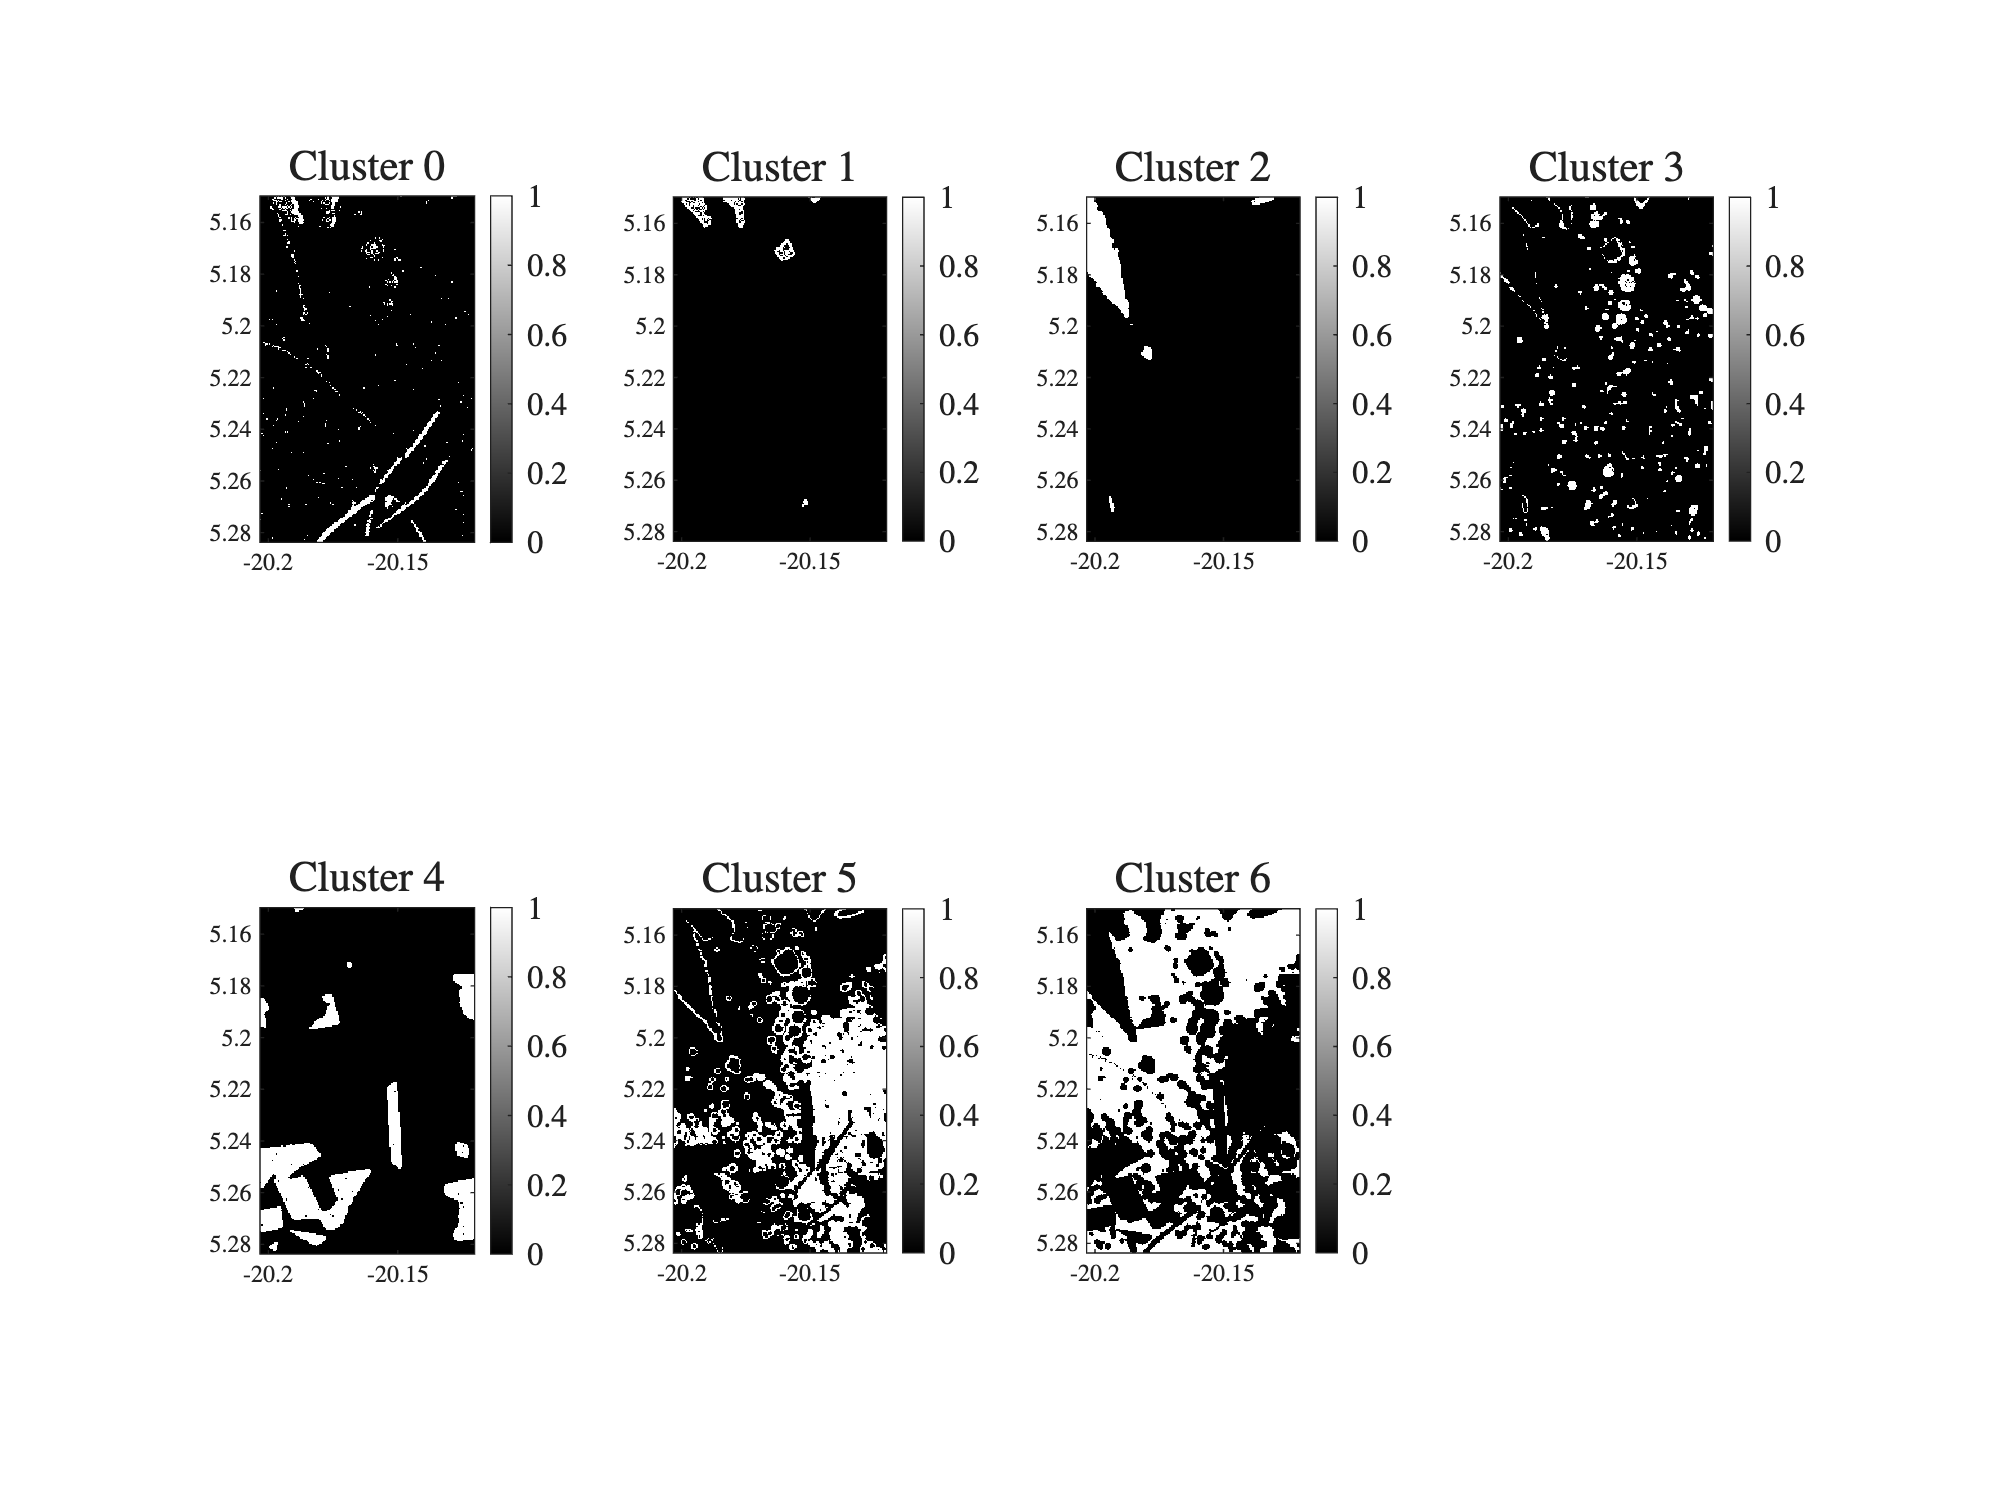


% plot clusters separately
fh10 = figure(10); clf;
set(fh10,'Units','inches','Position',[1 1 16 12]);

Nrow = floor(sqrt(c+1));
Ncol = ceil((c+1)/Nrow);

for nplt=1:c+1
    subplot(Nrow,Ncol,nplt)
    imagesc(X,Z,fliplr(reshape(Icfull==(nplt-1),nx,nz).')); colormap(gray); colorbar(TL{:},FS{:}); axis equal tight;
    set(gca,TL{:})
    title(['Cluster ',int2str(nplt-1)],FL{:},TX{:})
end

Cluster compositions mean (wt% SiO$_2$, TiO$_2$, Al$_2$O$_3$, FeO, MgO, CaO, Na$_2$O, K$_2$O)

disp(ClstOxdMean*100)

    5.1079   15.9300    3.0467   70.7836    2.6531    0.8551    0.3261    0.2439    0.7126    0.3411
   51.0973    1.1829    2.3276   14.3587   14.1099   15.3846    0.3842    0.1602    0.5291    0.4654
   55.5303    3.3999   10.6778   13.3994    2.4423    6.2911    1.2424    3.0774    3.7234    0.2159
   59.6447    0.3039   23.8991    1.4784    0.2184    6.9697    6.0910    1.1428    0.1758    0.0761
   64.8342    2.1593   13.0298    8.2739    1.4989    3.4950    1.0324    4.0547    1.4090    0.2128
   68.4097    1.7481   13.9890    6.0294    1.0276    2.3999    0.9938    4.4771    0.7621    0.1634



Cluster compositions standard deviation (wt% SiO$_2$, TiO$_2$, Al$_2$O$_3$, FeO, MgO, CaO, Na$_2$O, K$_2$O)

disp(ClstOxdStd*100)

    7.2087    2.3288    1.5596    8.7131    0.7230    1.5278    0.4523    0.3497    1.3122    0.0874
    2.2147    0.5766    1.0847    2.3876    2.0537    2.6088    0.2126    0.3666    1.1905    0.0714
    5.5250    1.2137    1.9058    4.4268    1.3463    2.0004    0.7345    0.7719    1.5240    0.0514
    2.4037    0.3890    2.2664    1.4580    0.3940    1.5857    0.7303    0.5186    0.4292    0.0379
    2.4304    0.4027    0.8856    1.8020    0.4775    0.8416    0.4222    0.3076    0.5495    0.0324
    1.6336    0.2878    0.6885    1.1510    0.3176    0.5634    0.4180    0.2774    0.3261    0.0314

